# Sign Following Robot with ROS in MATLAB

This example shows you how to use MATLAB® to control a simulated robot running on a separate ROS-based simulator over a ROS network. It then shows how to generate a ROS node for the control algorithm and deploy it to the remote device running ROS. The example shown here uses ROS and MATLAB for simulation, and MATLAB Coder™ for code generation and deployment. For the other examples with ROS 2 or Simulink®, see:

- [Sign Following Robot with ROS in Simulink](docid:ros_ug#mw_75fab4bc-81a3-4a4c-8ba8-c49aeb3692d4)

- [Sign Following Robot with ROS 2 in MATLAB](docid:ros_ug#mw_72854276-4bcd-45dc-b5d6-b9395ee621bc)

- [Sign Following Robot with ROS 2 in Simulink](docid:ros_ug#mw_62e18363-f79e-4645-86c9-65db0ed87762)

In this example, you run MATLAB script that implements a sign-following algorithm and controls the simulated robot to follow a path based on signs in the environment. The algorithm receives the location information and camera information from the simulated robot, which is running in a separate ROS-based simulator. The algorithm detects the color of the sign and sends the velocity commands to turn the robot based on the color. In this example, the algorithm is designed to turn left when robot encounters a blue sign and turn right when robot encounters a green sign. Finally the robot stops when it encounters a red sign.

## Connect to a Robot Simulator

Start a ROS-based simulator for a differential-drive robot and configure MATLAB® connection with the robot simulator. 

To follow along with this example, download a virtual machine using instructions in [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug#mw_9c45a664-ab3d-48a5-a65a-52913b8532b5).

- Start the Ubuntu® virtual machine desktop.

- In the Ubuntu desktop, click the **Gazebo Sign Follower ROS** icon to start the Gazebo world built for this example.

- Specify the IP address and port number of the ROS master in Gazebo so that MATLAB® can communicate with the robot simulator. For this example, the ROS master in Gazebo is `http://192.168.192.129:11311 `and your host computer address is `192.168.31.1`.

- Start the ROS 1 network using `rosinit`.

masterIP = '192.168.210.80';
rosinit(masterIP,11311)

The global ROS node is already initialized and connected to the master at URI "http://192.168.210.80:11311". If you want to restart the
global node, call "rosshutdown" first.

## Setup ROS Communication

Create publishers and subscribers to relay messages to and from the robot simulator over ROS network. You need subscribers for the image and odometry data. To control the robot, set up a publisher to send velocity commands using `/cmd_vel`.  The `rossubscriber` and `rospublisher` functions support code generation for message structures only. To return a message structure, specify the name-value pair argument, `"DataFormat","struct"`, when creating subscribers and publishers.

imgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");

odomSub = rossubscriber("/odom","nav_msgs/Odometry","DataFormat","struct");

[velPub, velMsg] = rospublisher("/cmd_vel", "geometry_msgs/Twist","DataFormat","struct");

Define the image processing color threshold parameters. Each row defines the threshold values for the different colors.

colorThresholds = [100 255 0 55 0 50; ... % Red
                   0 50 50 255 0 50; ...  % Green
                   0 40 0 55 50 255]';    % Blue

## Create Sign Following Controller Using Stateflow® Chart

This example provides an example helper MATLAB Stateflow® chart that takes in the image size, coordinates from processed image, and the robot odometry poses. The chart provides linear and angular velocity to drive the robot based on these inputs.

controller = ExampleHelperSignFollowingControllerChart;
%open('ExampleHelperSignFollowingControllerChart');

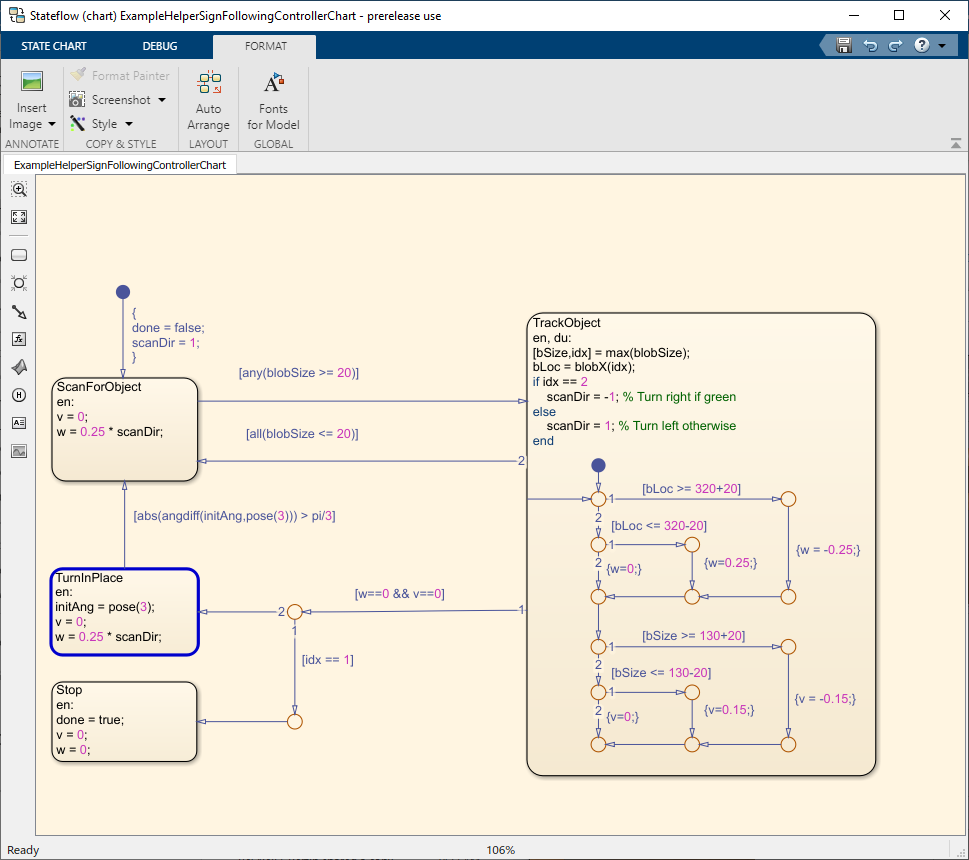

## Run Control Loop

This section runs the controller to receive images and move the robot to follow the sign. The controller does the following steps:

- Gets the latest image and odometry message from the ROS network.

- Runs the algoritm for detecting image features (`ExampleHelperSignFollowingProcessImg`).

- Generates control commands from the Stateflow® chart using `step`.

- Publishes the velocity control commands to the ROS network.

 To visualize the masked image the robot sees, change the value of `doVisualization` variable to `true`.

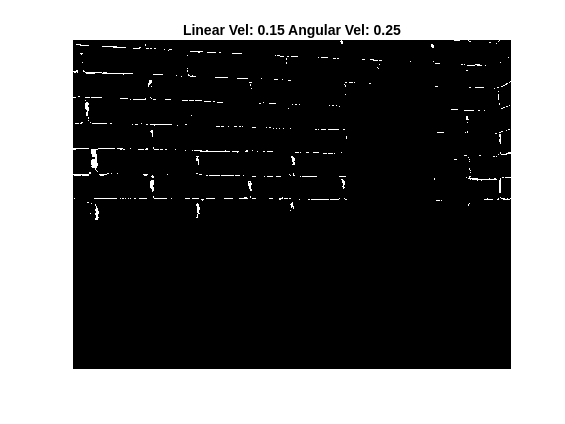

ExampleHelperSignFollowingSetupPreferences;

% Control the visualization of the mask
doVisualization = true;

r = rosrate(10);
receive(imgSub); % Wait to receive an image message before starting the loop
receive(odomSub);
while(~controller.done)
    % Get latest sensor messages and process them
    imgMsg = imgSub.LatestMessage;
    odomMsg = odomSub.LatestMessage;
    [img,pose] = ExampleHelperSignFollowingROSProcessMsg(imgMsg, odomMsg);
    
    % Run vision and control functions
    [mask,blobSize,blobX] = ExampleHelperSignFollowingProcessImg(img, colorThresholds);
    step(controller,'blobSize',blobSize,'blobX',blobX,'pose',pose);
    v = controller.v;
    w = controller.w;
    
    % Publish velocity commands
    velMsg.Linear.X = v;
    velMsg.Angular.Z = w;
    send(velPub,velMsg);
    
    % Optionally visualize
    % NOTE: Visualizing data will slow down the execution loop.
    % If you have Computer Vision Toolbox, we recommend using
    % vision.DeployableVideoPlayer instead of imshow.
    if doVisualization
        imshow(mask);
        title(['Linear Vel: ' num2str(v) ' Angular Vel: ' num2str(w)]);
        drawnow('limitrate');
    end
    % Pace the execution loop.
    waitfor(r);
end

You should see the robot moving in the ROS-based robot simulator as shown below.

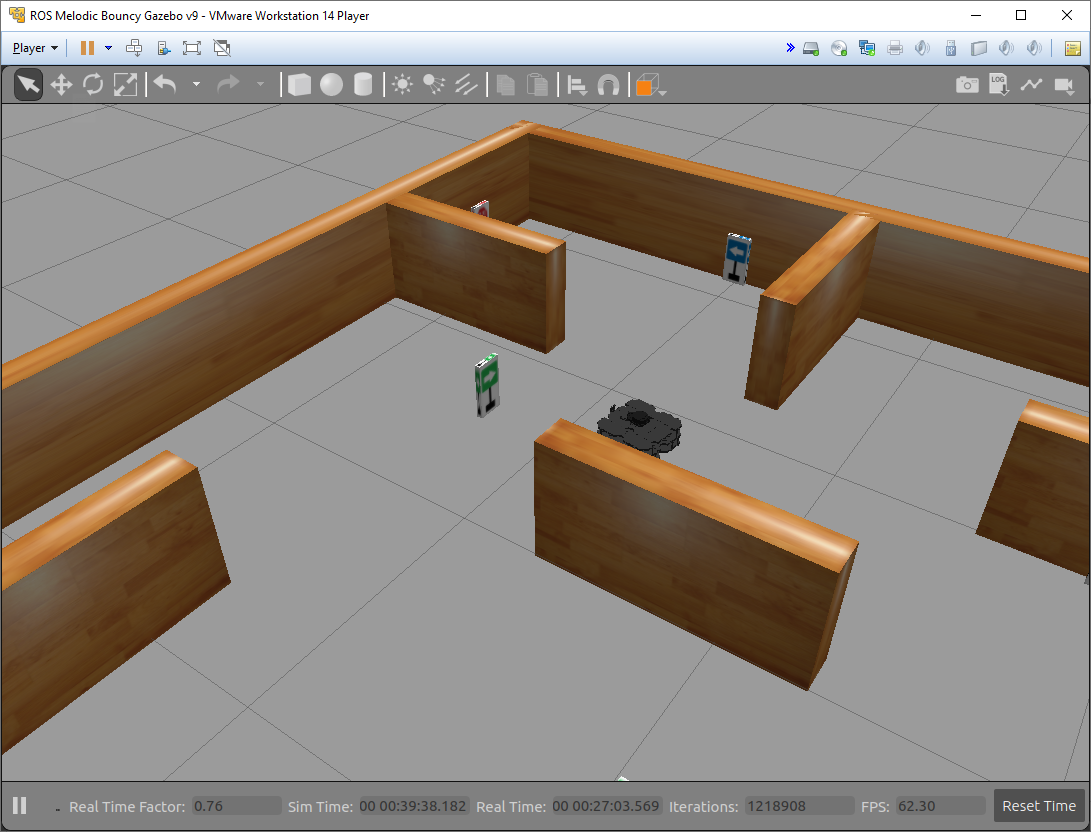

The robot follows the signs and stops at the final STOP sign. Reset the Gazebo scene after simulation using the `/gazebo/reset_simulation` service. Create a `rossvcclient` object for the service and use the `call` object function to call the service and reset the Gazebo simulation scene.

gazeboResetClient = rossvcclient('/gazebo/reset_simulation','DataFormat','struct');
call(gazeboResetClient);

## Generate and Deploy ROS Node

After the controller is verified, the next step is to generate a ROS node for the sign following robot algorithm using MATLAB Coder™ and deploy it on the remote Virtual Machine running Gazebo. Deployment enables ROS nodes to run on the remote machines directly, resulting in faster executions. Create a MATLAB Coder configuration object that uses `"Robot Operating System (ROS)" `hardware. For the Linux virtual machine for ROS Toolbox, set the following configuration parameters before remote deployment. Note that the actual values might be different for your remote device. Verify them before deployment. Set the build action to '`Build` `and` `Run'` so that the deployed ROS node starts running after code generation.

cfg = coder.config("exe");
cfg.Hardware = coder.hardware("Robot Operating System (ROS)");
cfg.Hardware.DeployTo = 'Remote Device';
cfg.Hardware.RemoteDeviceAddress = '192.168.192.129';
cfg.Hardware.RemoteDeviceUsername = 'user';
cfg.Hardware.RemoteDevicePassword = 'password';
cfg.Hardware.BuildAction = "Build and run";

Use `DeploySignFollowingRobotROS` function that contains the controller algorithm code verified in the previous section. Run the following command to generate the ROS node and deploy the controller. You should see the robot moving in the Gazebo world.

codegen DeploySignFollowingRobotROS -config cfg

'codegen' requires one of the following:
  MATLAB Coder
  Control System Toolbox
  HDL Coder

The robot follows the signs and stops at the final STOP sign. Reset the Gazebo scene after the node executes by calling the `rossvcclient` object, `gazeboResetClient`.

call(gazeboResetClient);

## Rerun the deployed node using `rosdevice `

To rerun the deployed ROS node from MATLAB, create a `rosdevice` object specifying the `deviceAddress,` `username,` and `password` values of the Virtual Machine running Gazebo. This establishes an SSH connection between the ROS device and MATLAB. Check the available nodes on the connected remote device. Verify that the deployed ROS node, `deploysignfollowingrobotros,` exists on the remote device .  

gazeboVMDevice = rosdevice('192.168.192.129','user','password');
gazeboVMDevice.AvailableNodes

 Run the ROS node deployed on the remote device using `runNode` function. The robot follows the signs and stops at the final STOP sign.

runNode(gazeboVMDevice,'deploysignfollowingrobotros')

*Copyright 2019 The MathWorks, Inc.*